## Probit - Gibbs

### Load data to use:

Apply the program to the dataset on mortgage applications (loanapp.csv).

% Specify the file path
filePath = 'loanapp.csv';

% Read the CSV file into a table
loanTable = readtable(filePath);

% remove the missing value from the dataset
loanTable = rmmissing(loanTable);

% Get the size of the dataset
datasetsize = size(loanTable);

% Display the size of the dataset
disp(['Number of Rows: ', num2str(datasetsize(1))]);      % 1777

Number of Rows: 1777


disp(['Number of Columns: ', num2str(datasetsize(2))]);   % 59

Number of Columns: 59


### Generate the y and X for the Probit model:

As this is a probit probit model, we assume


$$y_i = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i , \quad i = 1, \ldots, n$$


with $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$. In matrix form, this can be written as$y = X\beta + u$ where $y = (y_1, \ldots, y_n)$, $u = (u_1, \ldots, u_n)$ and 


$$X=\left\lbrack \begin{array}{ccccc}
1 & x_{11}  & x_{21}  & \cdots  & x_{\textrm{p1}} \\
1 & x_{12}  & x_{22}  & \cdots  & x_{\textrm{p2}} \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_{1n}  & x_{2n}  & \cdots  & x_{\textrm{pn}} 
\end{array}\right\rbrack$$


Then, we generate the dependent variable and independent variables X based on above form.

For the data, we will use:

    dependend varibale y: whether an individual was approved for a mortgage loan (approve)

    independent variable: 

- housing expenditures as percentage of total income (hrat)

- other obligations as percentage of total income (obrat)

- loan amount as percentage of house price (loanprc)

- unemployment rate in industry of occupation (unem)

- number of dependents (dep)

- dummy for high school education (sch)

- dummy for presence of cosigner (cosign)

- dummy for previous bankrupcy (pubrec)

- marriage status (married)

- dummy for white race (white)

- and dummy for sex (male)

We will have p = 11 and n equal to the the length of y vector.

% generate y and X

% generate outcome variable y
y_Data = loanTable(:, 'approve');
y = [table2array(y_Data)];

p = 11;
n = datasetsize(1);

X_Col = {'hrat', 'obrat', 'loanprc', 'unem', 'dep', 'sch', 'cosign', 'pubrec', 'married', 'white', 'male'}; 
% Extract the selected columns from the table
X_Data = loanTable(:, X_Col);

% generate X
X = [ones(n, 1), table2array(X_Data)];       % n * (p+1)

### Set prior hyperparameters:

Mentioned in the question, for all execises, we can use the following noninformative prior values:


$$\underline{B} = 1000 \cdot I_{p+1}$$
          
$$\underline{\alpha} = 0.02$$
            

             
$$\underline{\beta} = 0_{p+1}$$
                    
$$\underline{\delta} = 0.02$$
				

where $I_{p+1}$ is an identity matrix of size (p + 1) × (p + 1) and $0_{p+1}$ is a vector of zeros of dimension p + 1. 

% other noninformative prior values
I = eye(p + 1);                     % identity matrix of size (p+1)*(p+1)
zeroVector = zeros(p + 1, 1);       % a vector of zeros of dimension p + 1

B_underbar = 1000 * I;              % B = 1000·Ip+1; (p+1)*(p+1)
beta_underbar = zeroVector;         % β = 0p+1; (p+1)*1
alpha_underbar = 0.02;              % α = 0.02    
delta_underbar = 0.02;              % δ = 0.02

B_underbari = inv(B_underbar);

### Set algorithm values

1. Specify the burn-in and main iteration periods

We use a burn-in period of 5,000 iterations and keep 10,000 final iterations to estimate posterior means (for a total of 15,000 iterations). 

% iterations to estimate posterior means
burn_in_iter = 5000;                  % burn-in period of 5,000 iterations 
final_iter = 10000; 
nsim = burn_in_iter + final_iter + 1; % 15,000 final iterations

keep = (burn_in_iter + 2) : nsim;     % keep value for the final_iter

2. Specify initial values

In our model, we use a latent variable representation to formalize the model. Let $y^*$ be a latent unobserved variable that is related to the observed outcome y, where 


$$y_i^* = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i = x^\top \beta + u_i, \quad i = 1, \ldots, n$$


Here, $\beta = (\beta_0, \beta_1, \ldots, \beta_p)$ is a p + 1 vector of coefficients and we assume that with $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$ independently across units i. This latent variable represents the difference in utility between options$y_i = 1$and$y_i = 0$, also known as the marginal utility for individual i. 

To relate the latent variable $y_i ^ *$ to the observable action $y_i$, we assume the individual chooses $y_i = 1$whenever the utility of doing so is positive ($y_i ^* > 0 $) and chooses$y_i = 0$ otherwise. 

We also impose $\sigma^2$ = 1.

Then, we can initialize the value for coefficient vecor $\beta$ and $y^*$, and $u_i$.

% Initialize variables
beta_gibbs = zeros(nsim, p + 1);
y_star_gibbs = zeros(nsim, n);
beta_gibbs(1, :) = beta_underbar;

sigma2 = 1;                             % impose σ^2 = 1
u = normrnd(0, sqrt(sigma2), [n, 1]);   % u ~ N(0, σ^2) with n*1

3. Gibbs sampling:

The posterior, $p(y^*,\beta|y) \propto p(y|y^*,\beta) p(y^*,\beta)$.

We would write the likelihood of $y$ in terms of $\beta$ and $y^*$, which is $p(y|\beta, y^*)$, and it should follow the probit model. 

Then for the prior, we have $p(y^*,\beta) = p(y^*|\beta)p(\beta)$ with


$$p(y^*|\beta) = \sum_{i=1}^{n} \text{N}(y_i^*|x_i^{\top}, 1)$$



$$p(\beta) = \text{N}_{p+1}(\underline{\beta}, \underline{B})$$


For the latent variable$y^*$, we define two sets $C_0$ and $C_1$ for the observations with outcome 0 or 1, i.e., $C_0 = \{ i: y_i = 0\}$and $C_1 = \{ i: y_i = 1\}$. We can then obtain the conditional posteriors as

For all $i \in C_0$, $y_i^* |\beta,y \sim \text{TN}_{(-\infty,0]}(x_i^\top\beta,1)$

Fot all $i \in C_1$, $y_i^* |\beta,y \sim \text{TN}_{(0,\infty)}(x_i^\top\beta,1)$

For prior $\beta$:


$$\beta|y^*, y \sim \text{N}_{p+1}(\bar{\beta}, \bar{B})

$$


We need to initialize the $y^*$ with the trauncated distribution.

% To compute the y_star
% set y_star(0) by y whether > 0, and it is a n d
prob = sum(y == 1) / n;
mean_value = norminv(prob, 0, 1);

y_star_1 = zeros(n, 1);   % initial y_star 

% truncated distribution
for t = 1 : n
    if y(t) == 1
        y_star_1(t) = mvnrnd(mean_value, 1);
        while y_star_1(t) <= 0
            y_star_1(t) = mvnrnd(mean_value, 1);
        end
    else
        y_star_1(t) = mvnrnd(mean_value, 1);
        while y_star_1(t) > 0
            y_star_1(t) = mvnrnd(mean_value, 1);
        end
    end
end

% combination
y_star_gibbs(1, :) = y_star_1;


Then we generalized our main simulation loop to get the posterior.

In each iteration, the value of $\beta $ will be updated by $y^*$ and the value of $y^*$will be updated with the calculated $\beta$. Then we implment for 15000 iteration.

% main simulation loop to get the posterior

for s = 2 : nsim
    % get beta(2) condition on y_star(1)
    B_bar = inv(X' * X ./ sigma2 + B_underbari);
    Beta_bar = B_bar * (X' * y_star_gibbs(s - 1, :)' ./ sigma2 + B_underbari * beta_underbar);

    beta_gibbs(s, :) = mvnrnd(Beta_bar, B_bar);

    % get y_star(2) condition on beta(2)
    % truncated distribution
    for i = 1 : n
        y_star_is = mvnrnd(X(i, :) * beta_gibbs(s, :)', 1);
        % positive for set C1
        if y(i) == 1
            while y_star_is <= 0
                y_star_is = mvnrnd(X(i, :) * beta_gibbs(s, :)', 1);
            end
        % negative for set C0
        else
            while y_star_is > 0
                y_star_is = mvnrnd(X(i, :) * beta_gibbs(s, :)', 1);
            end
        end
        % update y_star
        y_star_gibbs(s, i) = y_star_is;
    end
end

### Summary of posteriors:

We should drop the value for the burn-in iterations and only keep the value for the last 10000 iterations.

% Remove the Burn-in iterations and only keeop the final iteration betas
% Store samples after burn-in iterations
beta_final = beta_gibbs(keep, :);
y_star_final = y_star_gibbs(keep, :);

% estimate
beta_means = mean(beta_final)';
beta_medians = median(beta_final)';
beta_sds = std(beta_final)';
y_star_means = mean(y_star_final)';
y_star_medians = median(y_star_final)';
y_star_sds = std(y_star_final)';

%print
beta = [beta_means, beta_medians]';
row = {'mean', 'median'};
array2table(beta, 'RowNames', row)

ans = 2×12 table
              beta1       beta2        beta3       beta4        beta5        beta6        beta7       beta8       beta9      beta10     beta11      beta12  
              ______    _________    _________    ________    _________    _________    _________    ________    ________    _______    _______    _________

    mean      2.3201    0.0088148    -0.029765      -0.948     -0.04087     -0.01818    0.0024099    0.076348     -0.9593    0.28224    0.64818    -0.025783
    median    2.3198    0.0088551    -0.029845    -0.94612    -0.0410

 Let's also get the trace plots, density plots and autocorrelation plots.

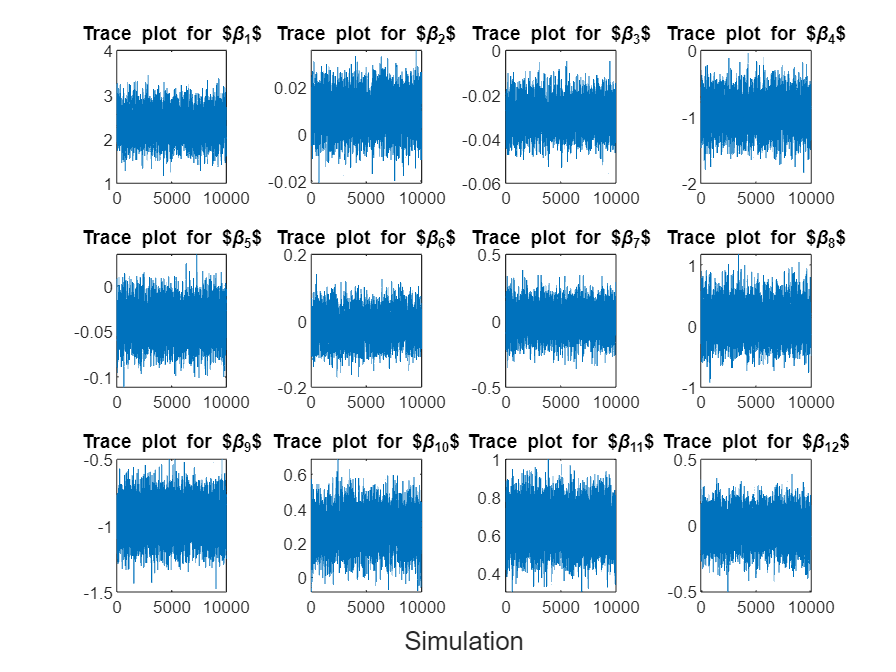

% Trace plots
figure
t = tiledlayout(3, 4);
for j = 1:p+1
    nexttile
    plot(beta_final(:, j))
    hold on
    title("Trace plot for $\beta_{" + j + "}$")
    hold off
end
xlabel(t, "Simulation")

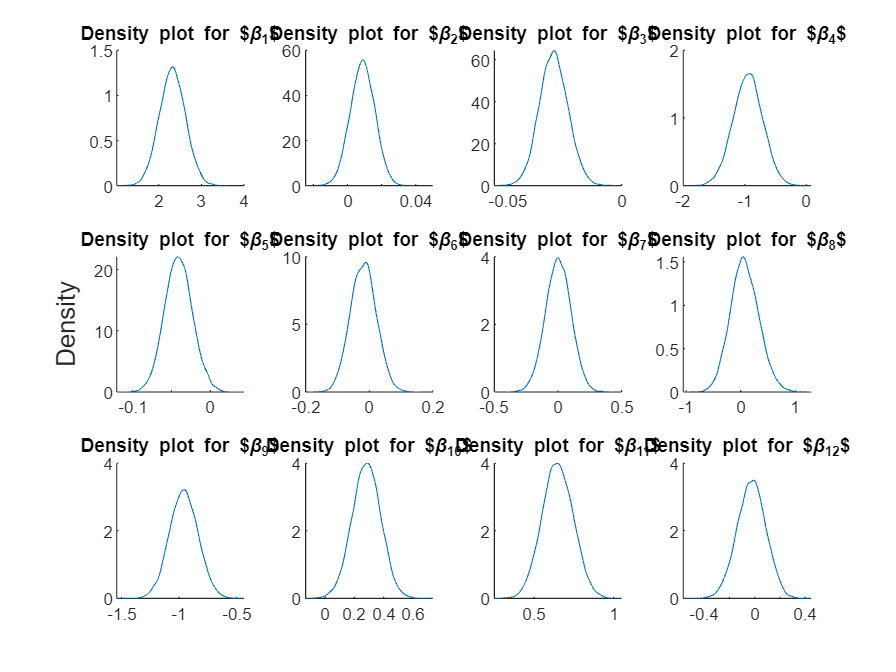


% Density plots
figure
t = tiledlayout(3, 4);
for j = 1:p+1
    nexttile
    hold on
    ksdensity(beta_final(:, j))
    hold off
    title("Density plot for $\beta_{" + j + "}$")
end
ylabel(t, "Density")

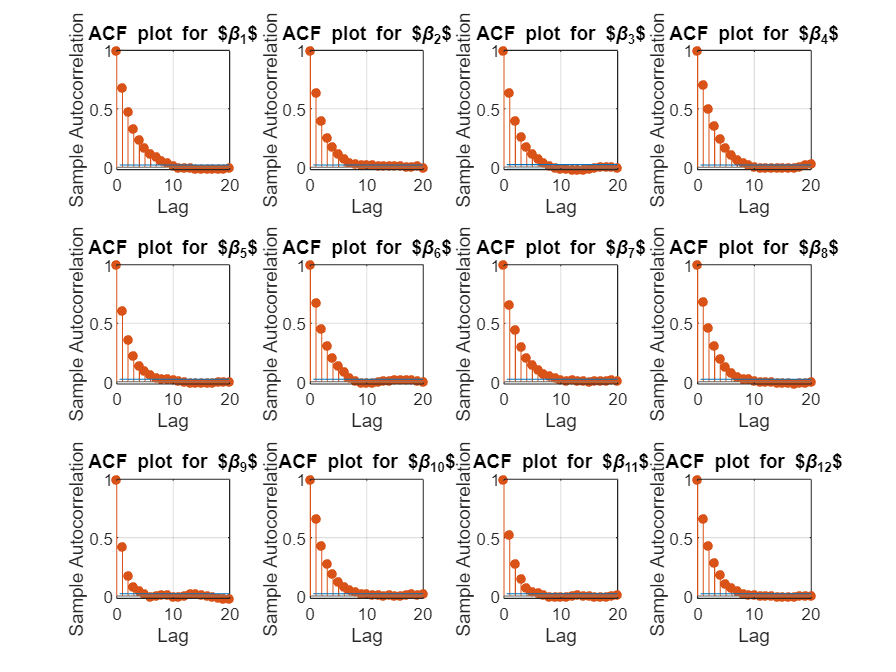

% Autocorrelation plots
figure
tiledlayout(3, 4);
for j = 1:p+1
    nexttile
    autocorr(beta_final(:, j))
    title("ACF plot for $\beta_{" + j + "}$")
end

### Marginal Effects:

To explain the effect of each $\beta_i$ on the outcome $y$ in the Probit model, we need to take the marginal effects on our $\beta_i$.

% Assuming beta_draws is your matrix of posterior draws
% Each row in beta_draws is a draw from the posterior distribution
% Columns represent different coefficients

% Assuming X is your data matrix (excluding the dependent variable)
% Initialize matrix to store predicted probabilities
predicted_probs = zeros(size(X,1), size(beta_final,1));

for i = 1:size(beta_final,1)
    predicted_probs(:,i) = normcdf(X * beta_final(i,:)');
end

% Initialize matrix to store marginal effects
marginal_effects = zeros(size(X,2), size(beta_final,1));

for i = 1:size(beta_final,1)
    % Calculate the linear predictor for this draw
    z = X * beta_final(i,:)';
    % Calculate the PDF of the normal distribution at these values
    pdf_values = normpdf(z);
    % Calculate marginal effects for each variable
    for j = 1:size(X,2)
        marginal_effects(j,i) = mean(pdf_values .* X(:,j) * beta_final(i,j));
    end
end

% Average the marginal effects across all draws
average_marginal_effects = mean(marginal_effects,2);
%print
marginal_beta = (average_marginal_effects)';
row = {'average_marginal_beta_effect'};
array2table(marginal_beta, 'RowNames', row)

ans = 1×12 table
                                    marginal_beta1    marginal_beta2    marginal_beta3    marginal_beta4    marginal_beta5    marginal_beta6    marginal_beta7    marginal_beta8    marginal_beta9    marginal_beta10    marginal_beta11    marginal_beta12
                                    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    _______________    _______________    _______________

    average_marginal_beta_effect       0.40094       